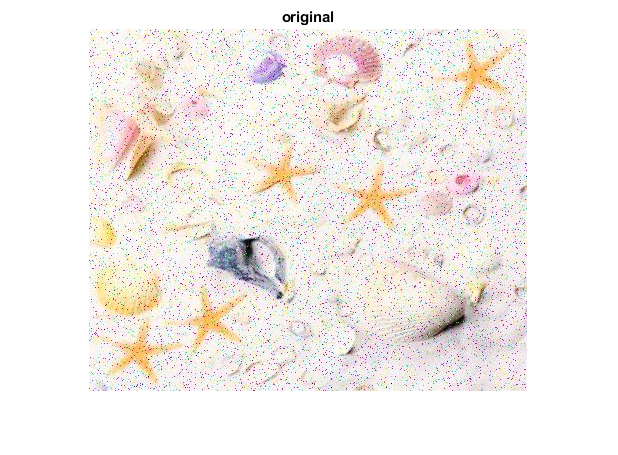

clear
% % %

im = imread("images\starfish.jpg");
imshow(im);
title("original");

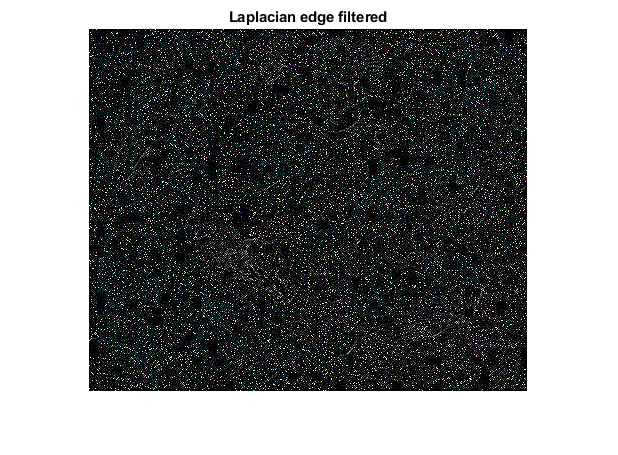

oim = im;
w = [0 1 0; 1 -4 1; 0 1 0]; % 3x3 laplacian

c = 2;
r = 5;
n = 0;

%  Laplacian edge filter
im1 = imfilter(im, w);
imshow(im1)
title("Laplacian edge filtered");

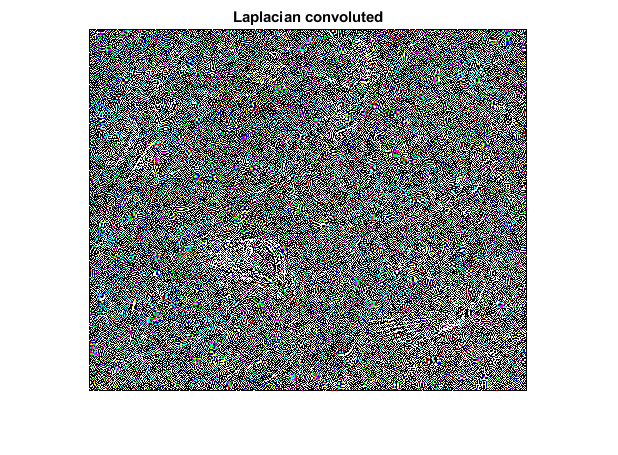

%  Laplacian edge filter CONVOLUTION
im2 = convn(im, w, 'same');
imshow(im2)
title("Laplacian convoluted");

%  DIFFERENCE between edges and convolution
noise = double(im2) - double(im1);
% imshow(noise)
% title("noise (conv - edge)");

% Split noise channels
[c1,c2,c3] = imsplit(im);
[n1,n2,n3] = imsplit(noise);
n1 = n1 > 0;
n1NoiseLevel = (sum(n1(:)) / numel(c1)) * 4

n1NoiseLevel = 0.1547

n2 = n2 > 0;
n2NoiseLevel = (sum(n2(:)) / numel(c2)) * 4

n2NoiseLevel = 0.1442

n3 = n3 > 0;
n3NoiseLevel = (sum(n3(:)) / numel(c3)) * 4

n3NoiseLevel = 0.1446

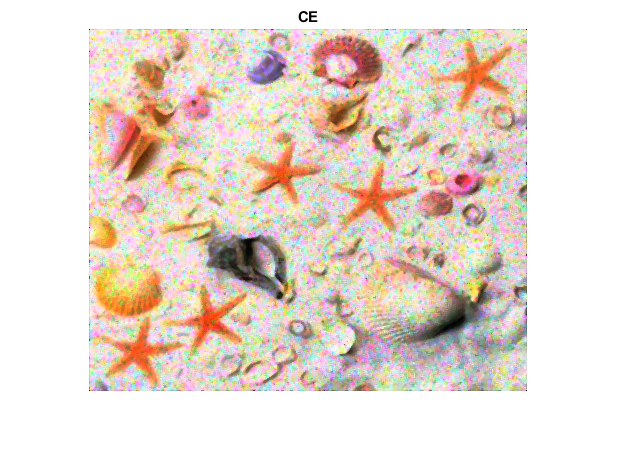


% 
% noiseThresh = 30;
% [c1,c2,c3] = imsplit(oim);
% [n1,n2,n3] = imsplit(noise);
% n1 = n1 > noiseThresh;
% n1NoiseLevel =  (sum(n1(:)) / numel(c1)) * 4
% n2 = n2 > noiseThresh;
% n2NoiseLevel =  (sum(n2(:)) / numel(c2)) * 4
% n3 = n3 > noiseThresh;
% n3NoiseLevel = (sum(n3(:)) / numel(c3)) * 4


filtered = oim;
[f1,f2,f3] = imsplit(filtered);
f1 = medfilt2(f1);
f2 = medfilt2(f2);
f3 = medfilt2(f3);
filtered = cat(3, f1, f2, f3);
% imshow(filtered);
% title("filtered");


% Denoise channels
[c1d,c2d,c3d] = imsplit(filtered);
c1d(n1) = f1(n1);
% c1d= imfilter(c1d, ones(3)/9, 'same');
c2d(n2) = f2(n2);
% c2d= imfilter(c2d, ones(3)/9, 'same');
c3d(n3) = f3(n3);
% c3d= imfilter(c3d, ones(3)/9, 'same');
denoised = cat(3, c1d,c2d,c3d);
% imshow(denoised);
% title("denoised");

denoised(:,:,1) = adapthisteq(denoised(:,:,1));
denoised(:,:,2) = adapthisteq(denoised(:,:,2));
denoised(:,:,3) = adapthisteq(denoised(:,:,3));
imshow(denoised);
title("CE");


% figure
% % Edge detection.
% subplot(r,c, (n + 1));
% im = imfilter(im, w);
% imshow(im);
% % Histogram of edges.
% subplot(r,c, (n + 1));
% imhist(im);
% 
% % Edge detection.
% subplot(r,c, (n + 1));
% c1 = imfilter(c1, w);
% imshow(c1);
% % Histogram of edges.
% subplot(r,c, (n + 1));
% imhist(c1);
% 
% % Edge detection.
% subplot(r,c, (n + 1));
% c2 = imfilter(c2, w);
% imshow(c2);
% % Histogram of edges.
% subplot(r,c, (n + 1));
% imhist(c2);
% 
% % Edge detection.
% subplot(r,c, (n + 1));
% c3 = imfilter(c3, w);
% imshow(c3);
% % Histogram of edges.
% subplot(r,c, (n + 1));
% imhist(c3);